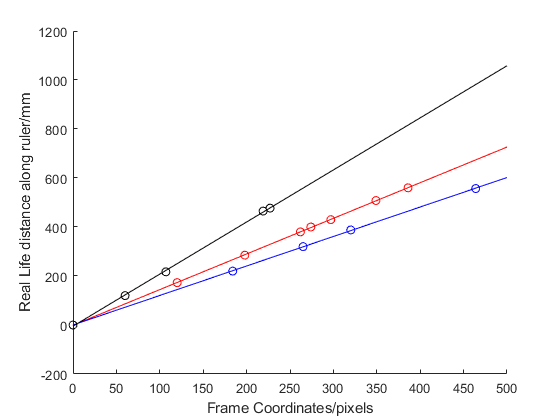

% at 1575 mm
frame = [0 274 198 349 120 262 386 297];
real_life = [0 400 285 508 173 380 560 430];
figure
hold on
scatter(frame, real_life,'ro')
eq1 = polyfit(frame, real_life, 1);
x = 0:1:500;
y1 = eq1(1)*x+ eq1(2);
plot(x,y1,'r')


% at 1400
frame2 = [0 320 184 265 464];
real_life2 = [0 388 220 320 557];
scatter(frame2, real_life2,'bo')
eq2 = polyfit(frame2, real_life2, 1);
y2 = eq2(1)*x+ eq2(2);
plot(x,y2,'b')

% at 2010
frame3 = [0 60 219 107 227];
real_life3 = [0 120 465 217 477];
scatter(frame3, real_life3,'ko')
eq3 = polyfit(frame3, real_life3, 1);
y3 = eq3(1)*x+ eq3(2);
plot(x,y3,'k')
xlabel("Frame Coordinates/pixels")
ylabel("Real Life distance along ruler/mm")
hold off

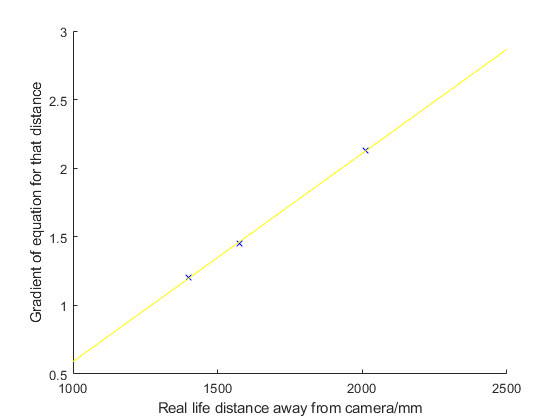

% Finding relationship between the gradients and distance away from the
% ball

gradients = [eq1(1) eq2(1) eq3(1)];
distances = [1575 1400 2010];

figure
hold on
scatter(distances, gradients,'bx')
eq4 = polyfit(distances, gradients, 1);
x = 1000:1:2500;
y4 = eq4(1)*x+ eq4(2);
plot(x,y4,'y')
xlabel("Real life distance away from camera/mm")
ylabel("Gradient of equation for that distance")
hold off

eq4

eq4 =     0.0015   -0.9274
